# s_opticsFresnel

Script to ilustrate how to calculate the Fresnel lens reflection and refraction

Based on the calculations described here:

This is the geometry of incident plane wave (I), the refracted light (R) and the transmitted light (T).

The index of refraction on the left is n1 and on the right is n2.

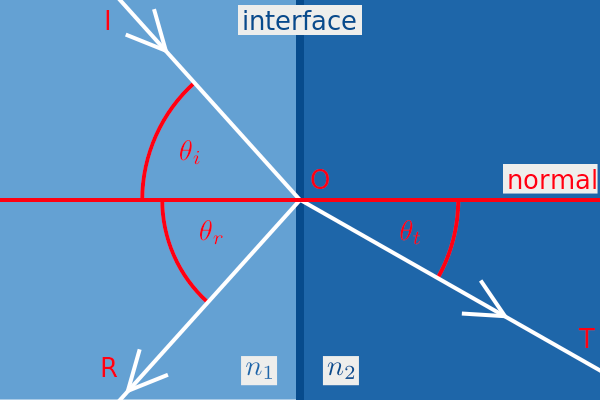

Wandell, 2022

## Setup

The Fresnel calculation is separated into the two different polarization angles, expressed as S and P.  For these calculations, we are going to plot the average of the two.  That is a good approximation for unpolarized light.

ieInit;    % Set up ISETCam

% A few parameters
n1 = 1.0;  % Air
n2 = 1.3;  % Glass
thetaIn = ((-25:25)/25)*(pi/2);   % Sample from -pi/2 to pi/2

## Definitions

The fraction of the incident [power](https://en.wikipedia.org/wiki/Power_(physics)) that is reflected from the interface is called the [*reflectance*](https://en.wikipedia.org/wiki/Reflectance) (or **reflectivity**, or **power reflection coefficient**) *R*, and the fraction that is refracted into the second medium is called the [*transmittance*](https://en.wikipedia.org/wiki/Transmittance) (or **transmissivity**, or **power transmission coefficient**) *T* . 

These are measured *at* each side of the interface and do not account for attenuation of a wave in an absorbing medium *following* transmission or reflection.[[2]](https://en.wikipedia.org/wiki/Fresnel_equations#cite_note-2)   Normally, there is no absorption (or almost none) in glass.

The reflected and transmitted light is related by


$$T=1-R$$


So, we only need to solve for one or the other. 

There is one other concept we need:  The impediance of the medium.  This is a simple quantity related to the index of refraction


$$Z_{i\;} =\frac{Z_0 }{n_i }$$


Where $Z_0$ is the [impedance of free space](https://en.wikipedia.org/wiki/Impedance_of_free_space).  The exact value of this parameter will not matter for this calculation because it divides out.

## Formula

The reflectance for the S and P polarization directions are given by these two formulae ([from the wikipedia page](https://en.wikipedia.org/wiki/Fresnel_equations)).  Notice that we only need to know the incidence angle and the two indices of refraction.

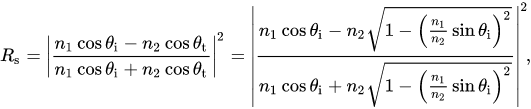

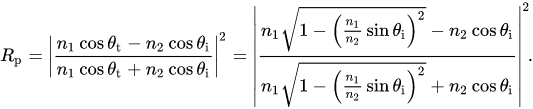

The transmittance is easily calculated from the reflectance.  We will generally calculate the average

 
$$R_{E\;} =\frac{\left(R_s +R_p \right)}{2}$$


## Examples